# **EEE-3102: Numerical Technique Laboratory **

# **Lab-2: Data writing to and reading from excel sheet and adding noise to signal and measurement of signal-to-noise ratio (SNR).**

#### **Lab Group- B**

#### **Name: M. Ashikuzzaman Kowshik**

#### **Class roll: AE-073-051**

## Exercise-01

x = -3*pi: pi/20: 3*pi

x =    -9.4248   -9.2677   -9.1106   -8.9535   -8.7965   -8.6394   -8.4823   -8.3252   -8.1681   -8.0111   -7.8540   -7.6969   -7.5398   -7.3827   -7.2257   -7.0686   -6.9115   -6.7544   -6.5973   -6.4403   -6.2832   -6.1261   -5.9690   -5.8119   -5.6549   -5.4978   -5.3407   -5.1836   -5.0265   -4.8695   -4.7124   -4.5553   -4.3982   -4.2412   -4.0841   -3.9270   -3.7699   -3.6128   -3.4558   -3.2987   -3.1416   -2.9845   -2.8274   -2.6704   -2.5133   -2.3562   -2.1991   -2.0420   -1.8850   -1.7279


y = sin(x) + sin(2*x) + sin(3*x) + sin(4*x)

y =     0.0000    0.2864    0.4208    0.3184   -0.0000   -0.4142   -0.7548   -0.8766   -0.7265   -0.3755    0.0000    0.1821   -0.0000   -0.5925   -1.4813   -2.4142   -3.0777   -3.2018   -2.6569   -1.5072    0.0000    1.5072    2.6569    3.2018    3.0777    2.4142    1.4813    0.5925   -0.0000   -0.1821    0.0000    0.3755    0.7265    0.8766    0.7548    0.4142   -0.0000   -0.3184   -0.4208   -0.2864    0.0000    0.2864    0.4208    0.3184   -0.0000   -0.4142   -0.7548   -0.8766   -0.7265   -0.3755


### *(a) Write the x and y values in an excel file.*

x_y = [x;y]

x_y =    -9.4248   -8.4248   -7.4248   -6.4248   -5.4248   -4.4248   -3.4248   -2.4248   -1.4248   -0.4248


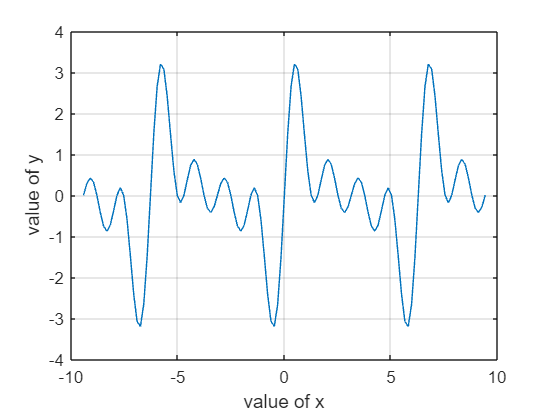


figure; 
plot(x,y)
xlabel('value of x') 
ylabel('value of y') 
grid on


writematrix(x_y, 'x_y.xls')

### *(b) Add 15 dB noise to y to obtain y1. Store y1 in an excel file.*

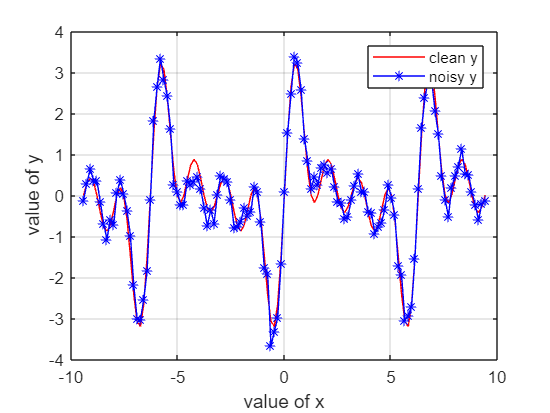

db=15; 
y1 = awgn(y,db,'measured'); 

figure;
plot(x,y,'r',x,y1,'-b*') 
xlabel('value of x')
ylabel('value of y')
legend('clean y','noisy y') 
grid on

### *(c) Read excels files for y and y1 and determine noise, n.*

m = readmatrix('x_y.xls')

m =    -9.4248   -9.2677   -9.1106   -8.9535   -8.7965   -8.6394   -8.4823   -8.3252   -8.1681   -8.0111   -7.8540   -7.6969   -7.5398   -7.3827   -7.2257   -7.0686   -6.9115   -6.7544   -6.5973   -6.4403   -6.2832   -6.1261   -5.9690   -5.8119   -5.6549   -5.4978   -5.3407   -5.1836   -5.0265   -4.8695   -4.7124   -4.5553   -4.3982   -4.2412   -4.0841   -3.9270   -3.7699   -3.6128   -3.4558   -3.2987   -3.1416   -2.9845   -2.8274   -2.6704   -2.5133   -2.3562   -2.1991   -2.0420   -1.8850   -1.7279
    0.0000    0.2864    0.4208    0.3184   -0.0000   -0.4142   -0.7548   -0.8766   -0.7265   -0.3755    0.0000    0.1821   -0.0000   -0.5925   -1.4813   -2.4142   -3.0777   -3.2018   -2.6569   -1.5072    0.0000    1.5072    2.6569    3.2018    3.0777    2.4142    1.4813    0.5925   -0.0000   -0.1821    0.0000    0.3755    0.7265    0.8766    0.7548    0.4142   -0.0000   -0.3184   -0.4208   -0.2864    0.0000    0.2864    0.4208    0.3184   -0.0000   -0.4142   -0.7548   -0.8766   -0.7265   -0


x = x_y(:,1)
y = x_y(:,2)

n = y1-y

n =     9.0521    9.7506    9.7658    9.5275    9.0030    8.7823    8.4912    8.0231    8.5893    8.6863    9.2441    9.5340    9.0411    8.6030    7.8741    6.3937    6.4495    6.6731    6.8511    7.6814    9.3750   10.5155   12.3949   12.7050   12.5426   11.4626   10.8291    9.7204    9.1897    8.9429    9.0108    9.4156    9.9417    9.7188   10.1746    9.6524    9.4428    9.0168    8.9707    8.6099    9.0122    9.4421    9.7160    9.8688    9.1951    9.1694    8.6320    8.6851    8.5729    8.7278
   -0.5020    0.1965    0.2117   -0.0266   -0.5511   -0.7718   -1.0629   -1.5310   -0.9648   -0.8678   -0.3100   -0.0201   -0.5129   -0.9511   -1.6800   -3.1604   -3.1046   -2.8809   -2.7030   -1.8727   -0.1790    0.9614    2.8408    3.1510    2.9885    1.9085    1.2751    0.1663   -0.3644   -0.6112   -0.5433   -0.1385    0.3876    0.1648    0.6206    0.0983   -0.1113   -0.5372   -0.5834   -0.9442   -0.5419   -0.1119    0.1619    0.3147   -0.3590   -0.3846   -0.9221   -0.8689   -0.9811   -0

### *(d) Plot x versus y, y1 and n in the same graph and use legend command to show them separately.*

clc;close all;
x = -3*pi: pi/20: 3*pi;

x =    -9.4248   -9.2677   -9.1106   -8.9535   -8.7965   -8.6394   -8.4823   -8.3252   -8.1681   -8.0111   -7.8540   -7.6969   -7.5398   -7.3827   -7.2257   -7.0686   -6.9115   -6.7544   -6.5973   -6.4403   -6.2832   -6.1261   -5.9690   -5.8119   -5.6549   -5.4978   -5.3407   -5.1836   -5.0265   -4.8695   -4.7124   -4.5553   -4.3982   -4.2412   -4.0841   -3.9270   -3.7699   -3.6128   -3.4558   -3.2987   -3.1416   -2.9845   -2.8274   -2.6704   -2.5133   -2.3562   -2.1991   -2.0420   -1.8850   -1.7279


y = sin(x) + sin(2*x) + sin(3*x) + sin(4*x);

y =     0.0000    0.2864    0.4208    0.3184   -0.0000   -0.4142   -0.7548   -0.8766   -0.7265   -0.3755    0.0000    0.1821   -0.0000   -0.5925   -1.4813   -2.4142   -3.0777   -3.2018   -2.6569   -1.5072    0.0000    1.5072    2.6569    3.2018    3.0777    2.4142    1.4813    0.5925   -0.0000   -0.1821    0.0000    0.3755    0.7265    0.8766    0.7548    0.4142   -0.0000   -0.3184   -0.4208   -0.2864    0.0000    0.2864    0.4208    0.3184   -0.0000   -0.4142   -0.7548   -0.8766   -0.7265   -0.3755


y1 = awgn(y,db,'measured');

y1 =     0.2622    0.2368    0.5029    0.2587    0.0575   -0.3040   -0.9093   -0.8078   -0.5760   -0.3523    0.4332    0.0297   -0.1846   -1.0308   -1.2533   -2.1971   -3.0977   -2.9767   -2.6109   -1.4344    0.0283    1.6174    2.6823    3.8998    2.7855    1.9498    1.1956    0.3187   -0.1086   -0.2243   -0.0547    0.5110    0.8240    1.0648    1.2001    0.7205   -0.3214   -0.9017   -0.1949   -0.7461    0.0167    0.2953    0.9786    0.3011   -0.1271   -0.3552   -0.6932   -0.8591   -0.8790   -0.6816


n = y1-y;

n =     0.2622   -0.0496    0.0821   -0.0597    0.0575    0.1102   -0.1545    0.0688    0.1505    0.0231    0.4332   -0.1524   -0.1846   -0.4382    0.2280    0.2172   -0.0200    0.2250    0.0460    0.0728    0.0283    0.1102    0.0255    0.6981   -0.2922   -0.4644   -0.2857   -0.2738   -0.1086   -0.0422   -0.0547    0.1356    0.0975    0.1881    0.4454    0.3063   -0.3214   -0.5833    0.2259   -0.4597    0.0167    0.0089    0.5578   -0.0173   -0.1271    0.0591    0.0616    0.0175   -0.1524   -0.3062


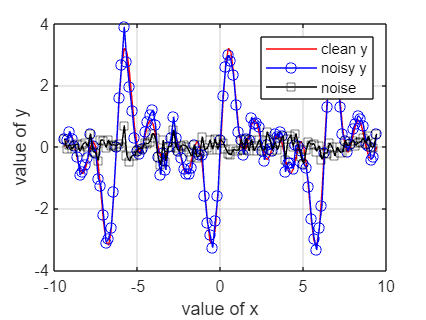


plot(x,y,'r',x,y1,'-bo',x,n,'-ks') 
xlabel('value of x')
ylabel('value of y')
legend('clean y','noisy y','noise') 
grid on

### *(e) Find the measured SNR added to y by using the excels files for y and y1.*

SNR = (snr(y,y1))

SNR = 0.0381